## History

2023-09-21, 

- Refer to https://www.mathworks.com/help/5g/ug/evm-measurement-of-5g-nr-pusch-waveforms.html

- Refer to https://www.mathworks.com/help/5g/ug/nr-pusch-throughput.html

## **Test Setup**

% select waveform format
if 1
    waveformFormat      = 'testModel'; % nr test model waveform
else
    waveformFormat      = 'pdsch'; % nr pdsch waveform
    waveformFormat      = 'pusch'; % nr pusch waveform
end

if strcmpi(waveformFormat, 'pusch')
    if 0
        ofdmFormat = 'DFT-s-OFDM';
    else
        ofdmFormat = 'CP-OFDM';
    end
end

% set channel bandwidth and scs
bwMHz                   = 100;
scskHz                  = 30;

% configure sampling rate
sampleRate              = 245.76e6;
carrierFreq_nSubframes_sampleRate_cell  = {0, [], sampleRate};

% configure duplex mode, only be used for test model generator
if 1
    dm = 'TDD';
else
    dm = 'FDD';
end
switch dm
    case 'TDD'
        isTDD           = 1;
    case 'FDD'
        isTDD           = 0;
end

% set RF impariment
isPhaseNoise            = 1;
isPropagationChannel    = 1;
isAWGN                  = 0;
isPwr                   = 1;

% set RF chain device
isLNA                   = 1;

% set number of antennas
NTxAnts = 1;
NRxAnts = 2;

% others settings
fnum                    = 0928; % plot
isDebug                 = 0;    % debug mode: demodulation
isSave                  = 1;    % save waveform

## **Phase Noise Model**

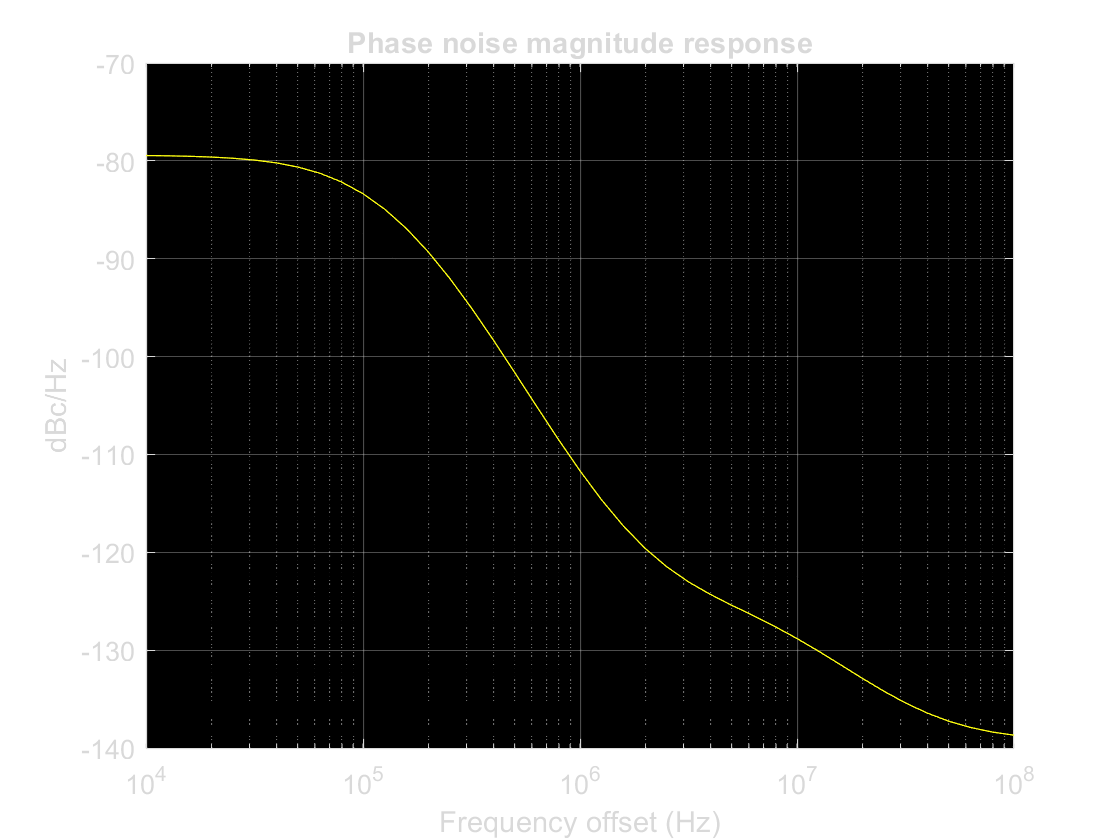

% apply phase noise model
if isPhaseNoise
    % set phase noise model
    sim.pn.FcHz     = 30e9;
    sim.pn.PNModel  = 'A'; % 'A' (TDoc R1-163984 Set A), 'B' (TDoc R1-163984 Set B), 'C' (TR 38.803)
    foffsetLog      = (4:0.1:log10(sampleRate/2)); % Model offset from 1e4 Hz to sr/2 Hz
    foffset         = 10.^foffsetLog;         % Linear frequency offset
    pn_PSD          = hPhaseNoisePoleZeroModel(foffset,sim.pn.FcHz,sim.pn.PNModel); % dBc/Hz

    % gen. phase noise model
    pnoise              = comm.PhaseNoise('FrequencyOffset',foffset,'Level',pn_PSD,'SampleRate',sampleRate);
    pnoise.RandomStream = "mt19937ar with seed";
    if 1
        % Visualize spectrum mask of phase noise
        figure
        semilogx(foffset,pn_PSD)
        xlabel('Frequency offset (Hz)')
        ylabel('dBc/Hz')
        title('Phase noise magnitude response')
        grid on
    end
else
    pnoise = [];
end

## **Propagation Channel Model**

% apply propagation channel model
if isPropagationChannel
    % set propagation channel model
    if 1
        ch.DelayProfile = 'CDL';
    else
        ch.DelayProfile = 'TDL';
    end

    %% Propagation Channel Model Construction
    % Create the channel model object for the simulation. Both CDL and TDL channel
    % models are supported [ <#13 5> ].

    % Constructed the CDL or TDL channel model object
    if contains(ch.DelayProfile,'CDL','IgnoreCase',true)

        channel = nrCDLChannel; % CDL channel object

        % Turn the overall number of antennas into a specific antenna panel
        % array geometry. The number of antennas configured is updated when
        % nTxAnts is not one of (1,2,4,8,16,32,64,128,256,512,1024) or nRxAnts
        % is not 1 or even.
        [channel.TransmitAntennaArray.Size,channel.ReceiveAntennaArray.Size] = ...
            hArrayGeometry(NTxAnts,NRxAnts);
        nTxAnts = prod(channel.TransmitAntennaArray.Size);
        nRxAnts = prod(channel.ReceiveAntennaArray.Size);
        NTxAnts = nTxAnts;
        NRxAnts = nRxAnts;
    else
        channel = nrTDLChannel; % TDL channel object

        % Set the channel geometry
        channel.NumTransmitAntennas = NTxAnts;
        channel.NumReceiveAntennas  = NRxAnts;
    end

    % Assign simulation channel parameters and waveform sample rate to the object
    channel.DelaySpread         = 300e-9;
    channel.MaximumDopplerShift = 5;
    channel.SampleRate          = sampleRate;
else
    channel = [];
end

## **PUSCH Waveform Generator**

switch waveformFormat
    case {'pusch','PUSCH'}
        if 1 % get NSizeGrid from bwMHz and scskHz
            spec = nrSpec;
            nrBwAndRBs_table = spec.nrBwAndRBs('fr1');
            NSizeGrid = nrBwAndRBs_table.([bwMHz+"MHz"])(find(scskHz == nrBwAndRBs_table.SCSkHz));
            if isnan(NSizeGrid)
                error('check the input of bwMHz and scskHz')
            end
        end

        % Set waveform type and PDSCH numerology (SCS and CP type)
        carrier = nrCarrierConfig;         % Carrier resource grid configuration
        carrier.NSizeGrid = NSizeGrid;            % Bandwidth in number of resource blocks (51 RBs at 30 kHz SCS for 20 MHz BW)
        carrier.SubcarrierSpacing = scskHz;    % 15, 30, 60, 120 (kHz)
        carrier.CyclicPrefix = 'Normal';   % 'Normal' or 'Extended' (Extended CP is relevant for 60 kHz SCS only)
        carrier.NCellID = 0;               % Cell identity

        % PUSCH/UL-SCH parameters
        pusch = nrPUSCHConfig;      % This PUSCH definition is the basis for all PDSCH transmissions in the BLER simulation
        puschExtension = struct();  % This structure is to hold additional simulation parameters for the UL-SCH and PUSCH

        % Define PUSCH time-frequency resource allocation per slot to be full grid (single full grid BWP)
        pusch.PRBSet = 0:carrier.NSizeGrid-1;                 % PUSCH PRB allocation
        pusch.SymbolAllocation = [0,carrier.SymbolsPerSlot];  % Starting symbol and number of symbols of each PUSCH allocation
        pusch.MappingType = 'A';     % PUSCH mapping type ('A'(slot-wise),'B'(non slot-wise))

        % Scrambling identifiers
        pusch.NID = carrier.NCellID;
        pusch.RNTI = 1;

        if 0
            % PDSCH resource block mapping (TS 38.211 Section 7.3.1.6)
            pdsch.VRBToPRBInterleaving = 0; % Disable interleaved resource mapping
            pdsch.VRBBundleSize = 4;
        end

        % Define the number of transmission layers to be used
        pusch.NumLayers = 1;            % Number of PDSCH transmission layers
        if 1
            % Define the transform precoding enbaling, layering and
            % transmission scheme
            switch ofdmFormat
                case 'DFT-s-OFDM'
                    pusch.TransformPrecoding = true;
                case 'CP-OFDM'
                    pusch.TransformPrecoding = false;
            end
            pusch.TransmissionScheme = 'nonCodebook'; % Transmission scheme ('nonCodebook','codebook')
            pusch.NumAntennaPorts = 1;        % Number of antenna ports for codebook based precoding
            pusch.TPMI = 0;                   % Precoding matrix indicator for codebook based precoding
        end

        % Define codeword modulation and target coding rate
        % The number of codewords is directly dependent on the number of layers so ensure that
        % layers are set first before getting the codeword number
        pusch.Modulation = 'QPSK';             % 'QPSK', '16QAM', '64QAM', '256QAM'
        puschExtension.TargetCodeRate = [193]/1024;   % Code rate used to calculate transport block sizes

        % DM-RS and antenna port configuration (TS 38.211 Section 7.4.1.1)
        if 0
            pdsch.DMRS.DMRSPortSet = 0:pdsch.NumLayers-1; % DM-RS ports to use for the layers
        end
        pusch.DMRS.DMRSTypeAPosition = 2;      % Mapping type A only. First DM-RS symbol position (2,3)
        pusch.DMRS.DMRSLength = 1;             % Number of front-loaded DM-RS symbols (1(single symbol),2(double symbol))
        pusch.DMRS.DMRSAdditionalPosition = 1; % Additional DM-RS symbol positions (max range 0...3)
        pusch.DMRS.DMRSConfigurationType = 1;  % DM-RS configuration type (1,2)
        pusch.DMRS.NumCDMGroupsWithoutData = 2;% Number of CDM groups without data
        pusch.DMRS.NIDNSCID = 0;               % Scrambling identity (0...65535)
        pusch.DMRS.NSCID = 0;                  % Scrambling initialization (0,1)
        if 1
            pusch.DMRS.NRSID = 0;                   % Scrambling ID for low-PAPR sequences (0...1007)
            pusch.DMRS.GroupHopping = 0;            % Group hopping (0,1)
            pusch.DMRS.SequenceHopping = 0;         % Sequence hopping (0,1)
        end

        if 0
            % PT-RS configuration (TS 38.211 Section 7.4.1.2)
            pdsch.EnablePTRS = 1;                  % Enable or disable PT-RS (1 or 0)
            pdsch.PTRS.TimeDensity = 1;            % PT-RS time density (L_PT-RS) (1, 2, 4)
            pdsch.PTRS.FrequencyDensity = 2;       % PT-RS frequency density (K_PT-RS) (2 or 4)
            pdsch.PTRS.REOffset = '00';            % PT-RS resource element offset ('00', '01', '10', '11')
            pdsch.PTRS.PTRSPortSet = [];           % PT-RS antenna port, subset of DM-RS port set. Empty corresponds to lower DM-RS port number

            % Reserved PRB patterns, if required (for CORESETs, forward compatibility etc)
            pdsch.ReservedPRB{1}.SymbolSet = [];   % Reserved PDSCH symbols
            pdsch.ReservedPRB{1}.PRBSet = [];      % Reserved PDSCH PRBs
            pdsch.ReservedPRB{1}.Period = [];      % Periodicity of reserved resources

            % Additional simulation and DL-SCH related parameters
            %
            % PDSCH PRB bundling (TS 38.214 Section 5.1.2.3)
            pdschExtension.PRGBundleSize = [];     % 2, 4, or [] to signify "wideband"
        end
        %
        % HARQ process and rate matching/TBS parameters
        puschExtension.XOverhead = 0; % Set PDSCH rate matching overhead for TBS (Xoh) 0
        puschExtension.NHARQProcesses = 16;    % Number of parallel HARQ processes to use
        puschExtension.EnableHARQ = true;      % Enable retransmissions for each process, using RV sequence [0,2,3,1]

        % LDPC decoder parameters
        % Available algorithms: 'Belief propagation', 'Layered belief propagation', 'Normalized min-sum', 'Offset min-sum'
        puschExtension.LDPCDecodingAlgorithm = 'Normalized min-sum';
        puschExtension.MaximumLDPCIterationCount = 6;

        % Define the overall transmission antenna geometry at end-points
        % If using a CDL propagation channel then the integer number of antenna elements is
        % turned into an antenna panel configured when the channel model object is created
        sim.NTxAnts = NTxAnts;              % Number of PDSCH transmission antennas (1,2,4,8,16,32,64,128,256,512,1024) >= NumLayers
        sim.NRxAnts = 2;                    % Number of UE receive antennas (1 or even number >= NumLayers)

        sim.NFrames = 2;
        sim.sampleRate = sampleRate;
        if 1 % Set demodulation
            sim.isSychronization = 1;
            sim.isOFDMDemodulate = 1;
            sim.isChannelEstimation = 1;
            sim.isCPE = 1;
            sim.isDecode = 1;
        end

        if isPropagationChannel
            switch class(channel)
                case 'nrCDLChannel'
                    [channel.TransmitAntennaArray.Size,channel.ReceiveAntennaArray.Size] = ...
                        hArrayGeometry(sim.NTxAnts,sim.NRxAnts);
                case 'nrTDLChannel'
                    % Set the channel geometry
                    channel.NumTransmitAntennas = NTxAnts;
                    channel.NumReceiveAntennas = NRxAnts;
            end
        end

        % generate waveform
        if 1
            [txWvCls, txWaveform, txConfig] = nrWaveformGen(waveformFormat, {carrier,pusch,puschExtension,sim},{}, ...
                carrierFreq_nSubframes_sampleRate_cell, {}, isTDD, fnum, isDebug, isSave);
        else
            [txWvCls, txWaveform, txConfig] = nrWaveformGen(waveformFormat, {carrier,pusch,puschExtension,sim},{}, ...
                carrierFreq_nSubframes_sampleRate_cell, {pnoise, channel}, isTDD, fnum, isDebug, isSave);
        end

        % export - carrier variables
        carrierBw = txWvCls.CarrierBw;
        channelBw = bwMHz * 1e6;
        bwInband = carrierBw * [-1 1]/2;

        % print
        fprintf('Generate %s waveform \n',txWvCls.WaveformInfo);
end

## **PDSCH Waveform Generator**

switch waveformFormat
    case {'pdsch','PDSCH'}
        if 1 % get NSizeGrid from bwMHz and scskHz
            spec = nrSpec;
            nrBwAndRBs_table = spec.nrBwAndRBs('fr1');
            NSizeGrid = nrBwAndRBs_table.([bwMHz+"MHz"])(find(scskHz == nrBwAndRBs_table.SCSkHz));
            if isnan(NSizeGrid)
                error('check the input of bwMHz and scskHz')
            end
        end

        % Set waveform type and PDSCH numerology (SCS and CP type)
        carrier = nrCarrierConfig;         % Carrier resource grid configuration
        carrier.NSizeGrid = NSizeGrid;            % Bandwidth in number of resource blocks (51 RBs at 30 kHz SCS for 20 MHz BW)
        carrier.SubcarrierSpacing = scskHz;    % 15, 30, 60, 120 (kHz)
        carrier.CyclicPrefix = 'Normal';   % 'Normal' or 'Extended' (Extended CP is relevant for 60 kHz SCS only)
        carrier.NCellID = 0;               % Cell identity

        % PDSCH/DL-SCH parameters
        pdsch = nrPDSCHConfig;      % This PDSCH definition is the basis for all PDSCH transmissions in the BLER simulation
        pdschExtension = struct();  % This structure is to hold additional simulation parameters for the DL-SCH and PDSCH

        % Define PDSCH time-frequency resource allocation per slot to be full grid (single full grid BWP)
        pdsch.PRBSet = 0:carrier.NSizeGrid-1;                 % PDSCH PRB allocation
        pdsch.SymbolAllocation = [0,carrier.SymbolsPerSlot];  % Starting symbol and number of symbols of each PDSCH allocation
        pdsch.MappingType = 'A';     % PDSCH mapping type ('A'(slot-wise),'B'(non slot-wise))

        % Scrambling identifiers
        pdsch.NID = carrier.NCellID;
        pdsch.RNTI = 1;

        % PDSCH resource block mapping (TS 38.211 Section 7.3.1.6)
        pdsch.VRBToPRBInterleaving = 0; % Disable interleaved resource mapping
        pdsch.VRBBundleSize = 4;

        % Define the number of transmission layers to be used
        pdsch.NumLayers = 1;            % Number of PDSCH transmission layers

        % Define codeword modulation and target coding rate
        % The number of codewords is directly dependent on the number of layers so ensure that
        % layers are set first before getting the codeword number
        if pdsch.NumCodewords > 1                             % Multicodeword transmission (when number of layers being > 4)
            pdsch.Modulation = {'16QAM','16QAM'};             % 'QPSK', '16QAM', '64QAM', '256QAM'
            pdschExtension.TargetCodeRate = [490 490]/1024;   % Code rate used to calculate transport block sizes
        else
            pdsch.Modulation = '16QAM';                       % 'QPSK', '16QAM', '64QAM', '256QAM'
            pdschExtension.TargetCodeRate = 490/1024;         % Code rate used to calculate transport block sizes
        end

        % DM-RS and antenna port configuration (TS 38.211 Section 7.4.1.1)
        pdsch.DMRS.DMRSPortSet = 0:pdsch.NumLayers-1; % DM-RS ports to use for the layers
        pdsch.DMRS.DMRSTypeAPosition = 2;      % Mapping type A only. First DM-RS symbol position (2,3)
        pdsch.DMRS.DMRSLength = 1;             % Number of front-loaded DM-RS symbols (1(single symbol),2(double symbol))
        pdsch.DMRS.DMRSAdditionalPosition = 2; % Additional DM-RS symbol positions (max range 0...3)
        pdsch.DMRS.DMRSConfigurationType = 2;  % DM-RS configuration type (1,2)
        pdsch.DMRS.NumCDMGroupsWithoutData = 1;% Number of CDM groups without data
        pdsch.DMRS.NIDNSCID = 1;               % Scrambling identity (0...65535)
        pdsch.DMRS.NSCID = 0;                  % Scrambling initialization (0,1)

        % PT-RS configuration (TS 38.211 Section 7.4.1.2)
        pdsch.EnablePTRS = 1;                  % Enable or disable PT-RS (1 or 0)
        pdsch.PTRS.TimeDensity = 1;            % PT-RS time density (L_PT-RS) (1, 2, 4)
        pdsch.PTRS.FrequencyDensity = 2;       % PT-RS frequency density (K_PT-RS) (2 or 4)
        pdsch.PTRS.REOffset = '00';            % PT-RS resource element offset ('00', '01', '10', '11')
        pdsch.PTRS.PTRSPortSet = [];           % PT-RS antenna port, subset of DM-RS port set. Empty corresponds to lower DM-RS port number

        % Reserved PRB patterns, if required (for CORESETs, forward compatibility etc)
        pdsch.ReservedPRB{1}.SymbolSet = [];   % Reserved PDSCH symbols
        pdsch.ReservedPRB{1}.PRBSet = [];      % Reserved PDSCH PRBs
        pdsch.ReservedPRB{1}.Period = [];      % Periodicity of reserved resources

        % Additional simulation and DL-SCH related parameters
        %
        % PDSCH PRB bundling (TS 38.214 Section 5.1.2.3)
        pdschExtension.PRGBundleSize = [];     % 2, 4, or [] to signify "wideband"
        %
        % HARQ process and rate matching/TBS parameters
        pdschExtension.XOverhead = 6*pdsch.EnablePTRS; % Set PDSCH rate matching overhead for TBS (Xoh) to 6 when PT-RS is enabled, otherwise 0
        pdschExtension.NHARQProcesses = 16;    % Number of parallel HARQ processes to use
        pdschExtension.EnableHARQ = true;      % Enable retransmissions for each process, using RV sequence [0,2,3,1]

        % LDPC decoder parameters
        % Available algorithms: 'Belief propagation', 'Layered belief propagation', 'Normalized min-sum', 'Offset min-sum'
        pdschExtension.LDPCDecodingAlgorithm = 'Normalized min-sum';
        pdschExtension.MaximumLDPCIterationCount = 6;

        % Define the overall transmission antenna geometry at end-points
        % If using a CDL propagation channel then the integer number of antenna elements is
        % turned into an antenna panel configured when the channel model object is created
        sim.NTxAnts = NTxAnts;                        % Number of PDSCH transmission antennas (1,2,4,8,16,32,64,128,256,512,1024) >= NumLayers
        if pdsch.NumCodewords > 1           % Multi-codeword transmission
            sim.NRxAnts = 8;                    % Number of UE receive antennas (even number >= NumLayers)
        else
            sim.NRxAnts = 2;                    % Number of UE receive antennas (1 or even number >= NumLayers)
        end
        if pdsch.NumLayers > sim.NTxAnts % 2023-10-05
            error('check the number of transmission layers and antennas')
        end
        sim.NFrames = 2;
        sim.sampleRate = sampleRate;
        if 1 % Set demodulation
            sim.isSychronization = 1;
            sim.isOFDMDemodulate = 1;
            sim.isChannelEstimation = 1;
            sim.isCPE = 1;
            sim.isDecode = 1;
        end

        if isPropagationChannel
            switch class(channel)
                case 'nrCDLChannel'
                    [channel.TransmitAntennaArray.Size,channel.ReceiveAntennaArray.Size] = ...
                        hArrayGeometry(sim.NTxAnts,sim.NRxAnts);
                case 'nrTDLChannel'
                    % Set the channel geometry
                    channel.NumTransmitAntennas = NTxAnts;
                    channel.NumReceiveAntennas = NRxAnts;
            end
        end

        % generate waveform
        [txWvCls, txWaveform, txConfig] = nrWaveformGen(waveformFormat, {carrier,pdsch,pdschExtension,sim},{}, ...
            carrierFreq_nSubframes_sampleRate_cell, {}, isTDD, fnum, isDebug, isSave);

        % export - carrier variables
        carrierBw = txWvCls.CarrierBw;
        channelBw = bwMHz * 1e6;
        bwInband = carrierBw * [-1 1]/2;

        % print
        fprintf('Generate %s waveform \n',txWvCls.WaveformInfo);
end

## **Test Model Waveform Generator**

- ulnrref: Fixed reference channel name

- bw: Bandwidth MHz

- scs: Subcarrier spacing override (15,30,60,120 kHz)

- dm: Duplexing mode override ("FDD","TDD")

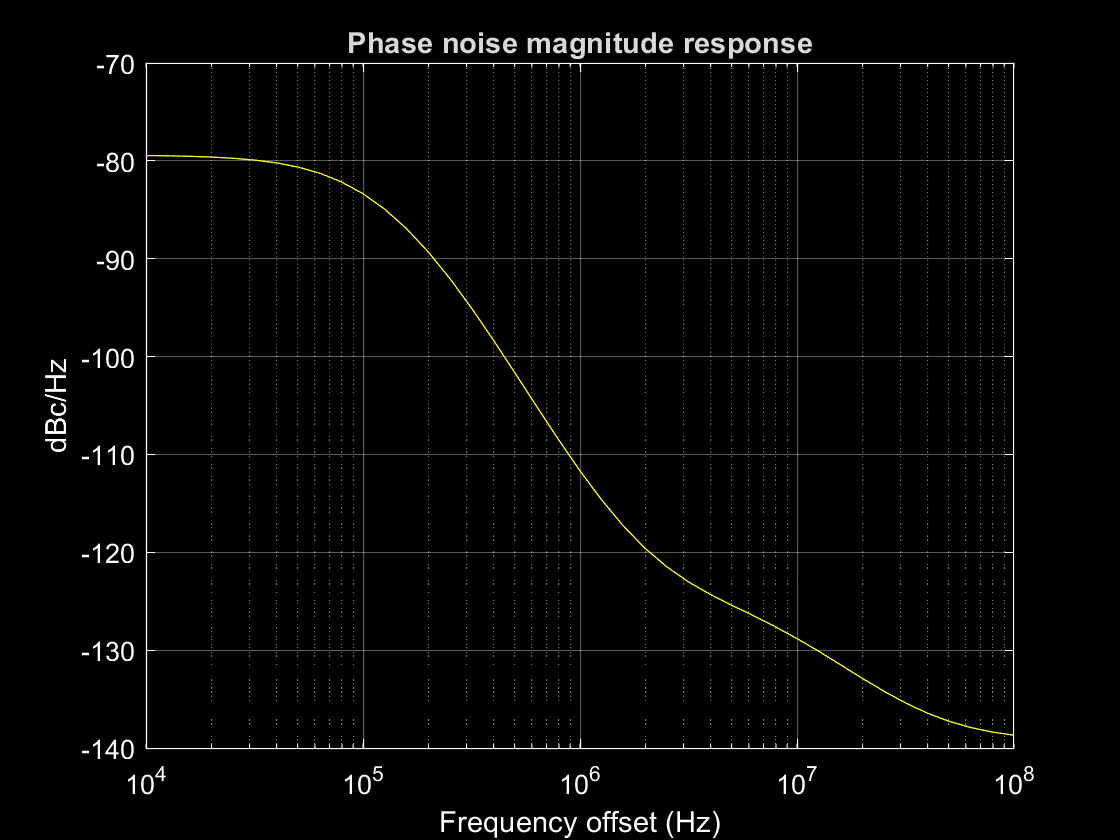

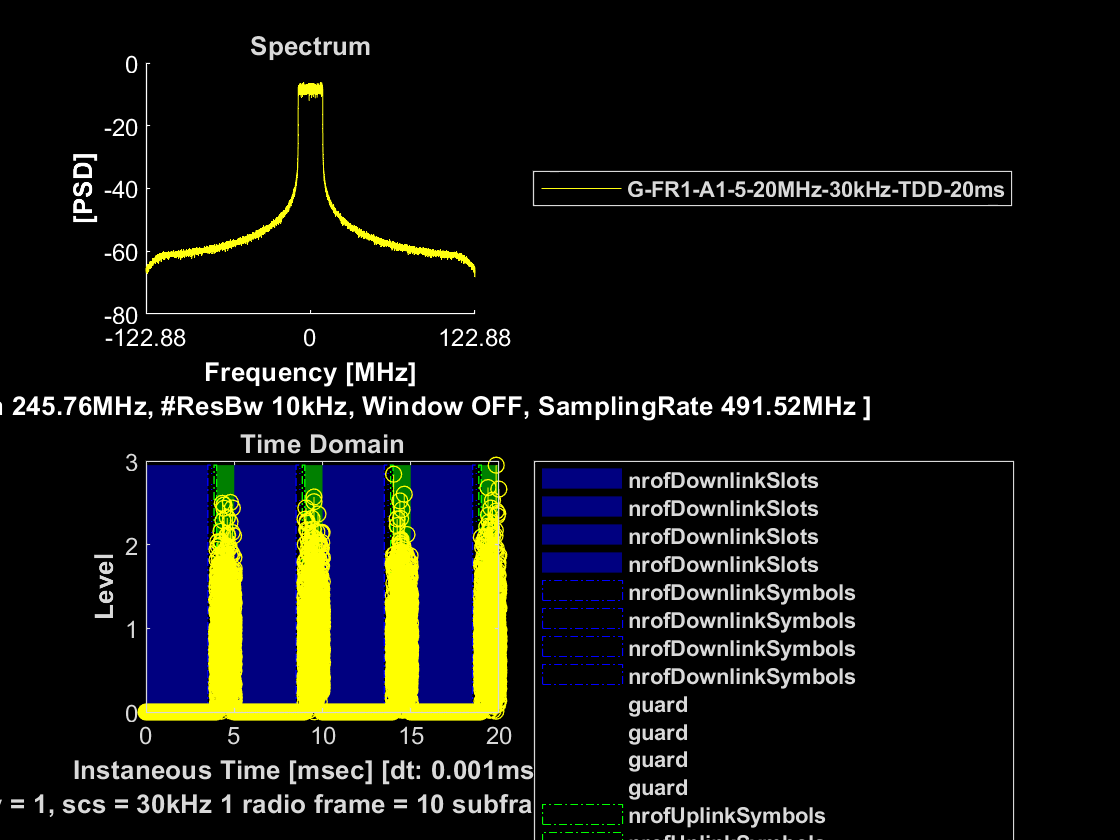


save to file G-FR1-A1-5-20MHz-30kHz-TDD-20ms.mat 


Generate G-FR1-A1-5-20MHz-30kHz-TDD-20ms waveform 


switch waveformFormat
    case {'TMs','FRCs','testModel'}
        % set fixed reference channel
        if 1
            ulnrref = "G-FR1-A1-5";
        else
            ulnrref = "G-FR1-A5-7"; % FRC
        end

        % set channel bandwidth, e.g., "100MHz"
        if 0
            bw      = bwMHz+"MHz";  % Bandwidth override (5,10,15,20,25,30,40,50,60,70,80,90,100,200,400 MHz)
        else
            bw = [];
        end

        % set subcarrier spacing, e.g., "30kHz"
        if 0
            scs     = scskHz+"kHz";  % Subcarrier spacing override (15,30,60,120 kHz)
        else
            scs = [];
        end

        dm      = dm;  % Duplexing mode override ("FDD","TDD")
        ncellid = [];  % Cell identity override (used to control scrambling identities)

        % Carrier configuration
        sampleRate;
        carrierFreq_nSubframes_sampleRate_cell;

        % others
        fnum;
        isDebug;
        isTDD;
        isSave;

        % Create generator object for the above PUSCH FRC reference model
        [txWvCls, txWaveform, txConfig] = nrWaveformGen(waveformFormat, {},{ulnrref,bw,scs,dm,ncellid}, ...
            carrierFreq_nSubframes_sampleRate_cell, {}, isTDD, fnum, isDebug, isSave);

        % export - carrier variables
        carrierBw = txWvCls.CarrierBw;
        channelBw = txWvCls.ChannelBw;
        bwInband = carrierBw * [-1 1]/2;

        % print
        fprintf('Generate %s waveform \n',txWvCls.WaveformInfo);
end

## **Apply Phase Noise Model**

if isPhaseNoise
    release(pnoise)
    % apply
    txWaveform_PN = txWvCls.setPhaseNoise(txWaveform, pnoise, sampleRate);
    % export
    txWaveform = txWaveform_PN;
end

Phase Noise Model Application ...


## **Apply Propagation Channel Model**

if isPropagationChannel
    % apply
    txWaveform_Ch = txWvCls.setPropagationChannel(txWaveform, channel, sampleRate);
    % export
    txWaveform = txWaveform_Ch;
end

Propagation Channel Model Construction ...


## **Assign Power to Waveform**

if isPwr
    % set power dBm
    pwrdBm = -80;

    for k=1:size(txWaveform,2)
        % apply
        rxWaveform(:,k) = pwrdB_adj(txWaveform(:,k), pwrdBm, 'dBm',[], sampleRate, bwInband, dm);
        % check
        pwrdBm_rxWv(:,k) = pwrdB(rxWaveform(abs(rxWaveform(:,k))>eps), sampleRate, bwInband, [], 'dBm', []);
        pwrdBm_txWv(:,k) = pwrdB(txWaveform(abs(txWaveform(:,k))>eps), [], [], [], 'dBm', []);
        % print
        fprintf('Set Ant.%d rxWaveform power %0.02fdBm \n',k,pwrdBm_rxWv(:,k))
    end
else
    rxWaveform = txWaveform;
    pwrdBm_rxWv(:,k) = pwrdB(rxWaveform(abs(rxWaveform(:,k))>eps), sampleRate, bwInband, [], 'dBm', []);
    % print
    fprintf('Get Ant.%d rxWaveform power %0.02fdBm \n',k,pwrdBm_rxWv(:,k))
end

Set Ant.1 rxWaveform power -80.00dBm 
Set Ant.2 rxWaveform power -80.00dBm 


## **Apply AWGN**

if isAWGN
    for k=1:size(rxWaveform,2)
        % set SNRdB
        SNRdB = 20;

        % Apply noise
        [rxWaveform_AWGN(:,k), noise] = noiseGen(rxWaveform(:,k), SNRdB, 'snr', [], sampleRate, bwInband, fnum+3, isTDD);
        % export
        rxWaveform(:,k) = rxWaveform_AWGN(:,k);
        % print
        fprintf('Set Ant.%d rxWaveform SNR %ddB \n',k,SNRdB)
        % check noise
        pwrNodBmHz = pwrdB(noise, [], [], [], 'dBm', []) - 10*log10(sampleRate);
    end
end

## **Plot Waveform**

- CCDF

- ACLR

Get Ant.1 rxWaveform PAPR 9.79dB 


Get Ant.1 rxWaveform ACLR min. 34.83dBc 


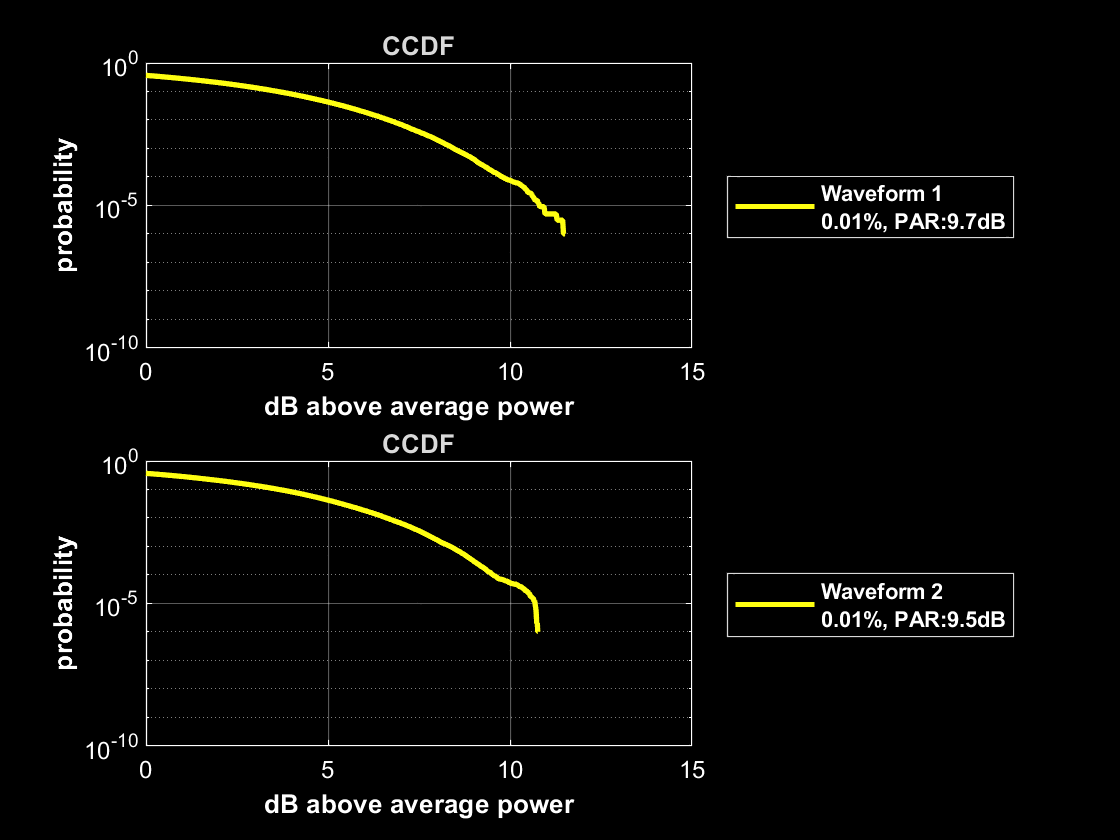

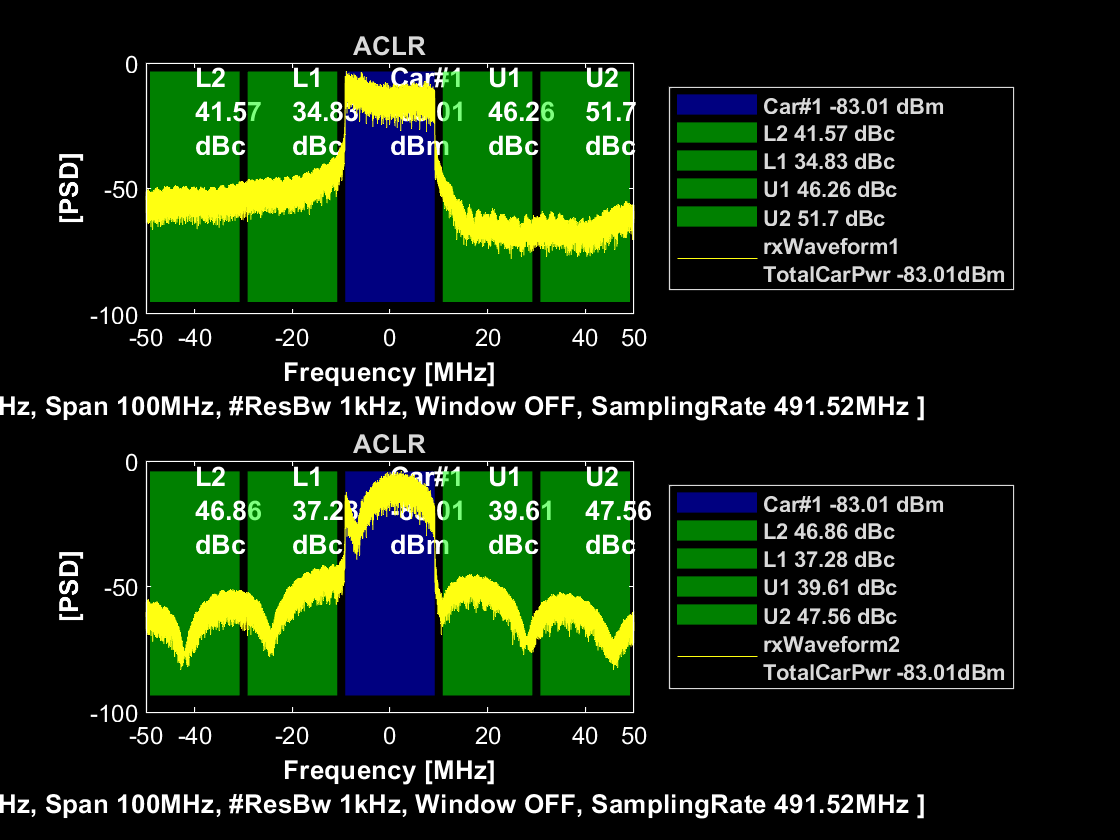

Get Ant.2 rxWaveform PAPR 9.52dB 


Get Ant.2 rxWaveform ACLR min. 37.28dBc 


for k=1:size(rxWaveform,2)
    paprDb = plotCCDF(rxWaveform(:,k),[],{[fnum+1013,size(rxWaveform,2),1,k],['Waveform ', num2str(k)],[],'blk'},1);
    aclr = plotACLR(rxWaveform(:,k),sampleRate,{carrierBw,channelBw},{1,0,isTDD},{[fnum+1014,size(rxWaveform,2),1,k],['rxWaveform', num2str(k)],'ACLR'},{0,5*channelBw});

    % print
    fprintf('Get Ant.%d rxWaveform PAPR %0.2fdB \n',k,paprDb)
    fprintf('Get Ant.%d rxWaveform ACLR min. %0.2fdBc \n',k,min(aclr.ACLRdBc))
end

## **Apply LNA **

- BPF/LNA/Gain/ADC... stage

s1, powerAmp.pa_amp.OPsat
PinDbm(Wide Band) is -79.9911, marginDb is 1072.2911, evmAmp is 0

s1, powerAmp.pa_amp.NF is 2.3dB, evmNF is 15.69

s2, powerAmp.pa_amp.OPsat
PinDbm(Wide Band) is -81.0462, marginDb is 55.0462, evmAmp is 0

s2, powerAmp.pa_amp.NF is 1.8dB, evmNF is 7.87

s3, powerAmp.pa_amp.OPsat
PinDbm(Wide Band) is -46.7775, marginDb is 1053.1775, evmAmp is 0

s3, powerAmp.pa_amp.NF is 16.4dB, evmNF is 2.09

s4, powerAmp.pa_amp.OPsat
PinDbm(Wide Band) is -63.16, marginDb is 53.36, evmAmp is 0

s4, powerAmp.pa_amp.NF is 1.8dB, evmNF is 1.05

s5, powerAmp.pa_amp.OPsat
PinDbm(Wide Band) is -45.3558, marginDb is 1036.8558, evmAmp is 0

s5, powerAmp.pa_amp.NF is 1.5dB, evmNF is 0.31

s6, powerAmp.pa_amp.OPsat
PinDbm(Wide Band) is -46.8554, marginDb is 62.8554, evmAmp is 0

s6, powerAmp.pa_amp.NF is 14dB, evmNF is 1.17



s1, powerAmp.pa_amp.OPsat
PinDbm(Wide Band) is -79.9998, marginDb is 1072.2998, evmAmp is 0

s1, powerAmp.pa_amp.NF is 2.3dB, evmNF is 15.89

s2, powerAmp.pa_amp.OPsat
PinDbm(Wide Band) is -81.0555, marginDb is 55.0555, evmAmp is 0

s2, powerAmp.pa_amp.NF is 1.8dB, evmNF is 7.86

s3, powerAmp.pa_amp.OPsat
PinDbm(Wide Band) is -46.7855, marginDb is 1053.1855, evmAmp is 0

s3, powerAmp.pa_amp.NF is 16.4dB, evmNF is 2.06

s4, powerAmp.pa_amp.OPsat
PinDbm(Wide Band) is -63.1681, marginDb is 53.3681, evmAmp is 0

s4, powerAmp.pa_amp.NF is 1.8dB, evmNF is 1.04

s5, powerAmp.pa_amp.OPsat
PinDbm(Wide Band) is -45.3634, marginDb is 1036.8634, evmAmp is 0

s5, powerAmp.pa_amp.NF is 1.5dB, evmNF is 0.31

s6, powerAmp.pa_amp.OPsat
PinDbm(Wide Band) is -46.8629, marginDb is 62.8629, evmAmp is 0

s6, powerAmp.pa_amp.NF is 14dB, evmNF is 1.16



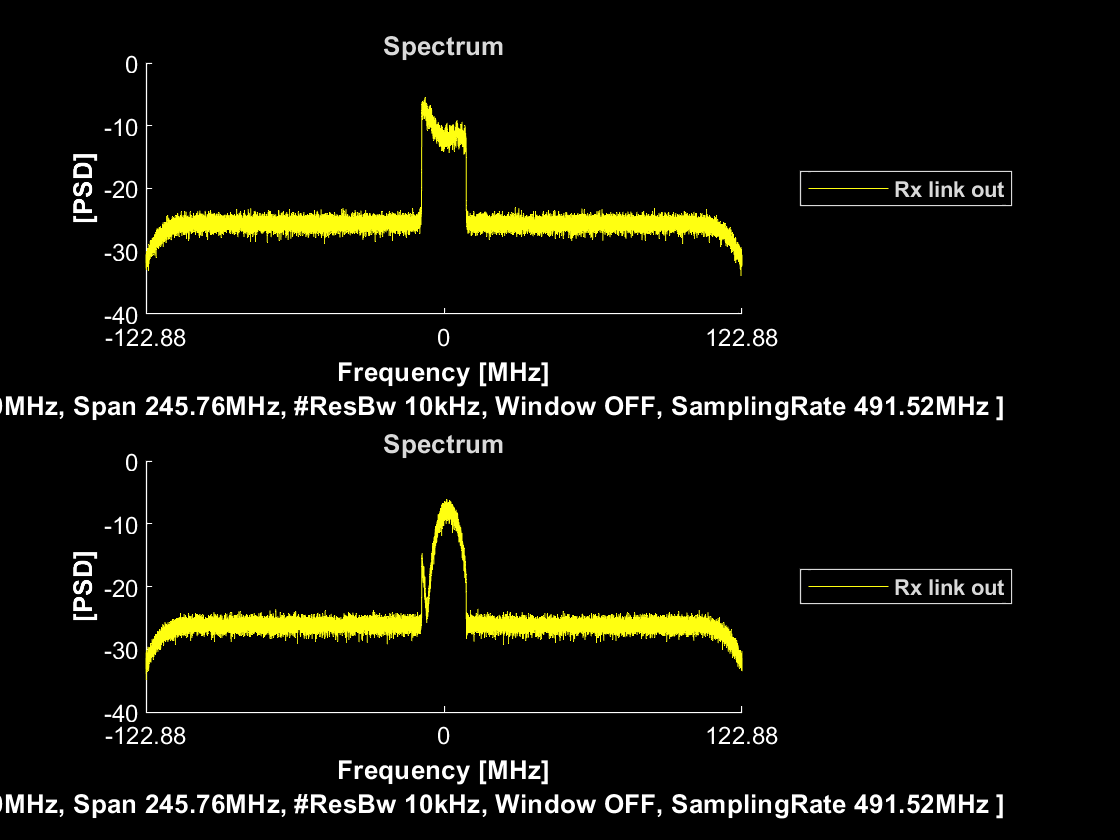

if isLNA
    rxWaveform_LNA = zeros(size(rxWaveform));
    for k=1:size(rxWaveform,2)

        % apply lna class
        if 1
            [rxWaveform_LNA(:,k),pwrdBm_rxWv2,evmLNA] = applyRxLink(rxWaveform(:,k), {}, {sampleRate, bwInband}, [1018,size(rxWaveform,2),1,k]);
        else
            [rxWaveform_LNA(:,k),pwrdBm_rxWv2,evmLNA] = applyRxLink(rxWaveform(:,k), {BPF;LNA;BPF2;LNA2;Loss;RxADC}, {sampleRate, bwInband}, [1018,size(rxWaveform,2),1,k]);
        end
    end
    rxWaveform = rxWaveform_LNA;
end

## **Measurements: EVM and Throughput**

The function, hNRPUSCHEVM, performs thest steps to decode and analyze the waveform:

- Coarse frequency offset estimation and correction

- Integer frequency offset estimation and correction

- Synchronization using the demodulation reference signal (DM-RS) over one frame for FDD (two frames for TDD)

- OFDM demodulation of the received waveform

- Fine frequency offset estimation and correction 

- Channel estimation

- Equalization

- Common Phase Error (CPE) estimation and compensation

- PUSCH EVM computation (enable the switch evm3GPP to process according to the EVM measurement requirements specified in TS 38.101-1 (FR1) or TS 38.101-2 (FR2), Annex F.


(22.50%) NSlot=8, transmission passed
(25.00%) NSlot=9, transmission passed
(47.50%) NSlot=18, transmission passed
(50.00%) NSlot=19, transmission passed
(72.50%) NSlot=28, transmission passed
(75.00%) NSlot=29, transmission passed
(97.50%) NSlot=38, transmission passed
(100.00%) NSlot=39, transmission passed
Throughput = 0.87028Mbps(100%)

EVM stats for BWP idx : 1
 RMS EVM, Peak EVM, slot 8: 14.722 45.489%
 RMS EVM, Peak EVM, slot 9: 14.723 54.705%
 RMS EVM, Peak EVM, slot 18: 15.311 58.065%
 RMS EVM, Peak EVM, slot 19: 14.517 50.523%
 RMS EVM, Peak EVM, slot 28: 15.336 66.791%
 RMS EVM, Peak EVM, slot 29: 14.781 60.837%
 RMS EVM, Peak EVM, slot 38: 14.836 54.168%
 RMS EVM, Peak EVM, slot 39: 15.365 62.518%
Averaged RMS EVM frame 0: 14.952%
Averaged RMS EVM frame 1: 14.952%
Averaged overall RMS EVM: 14.952%


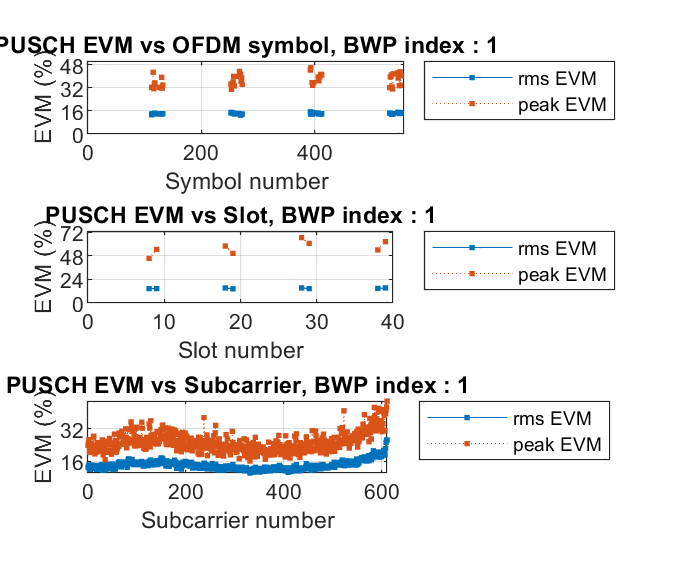

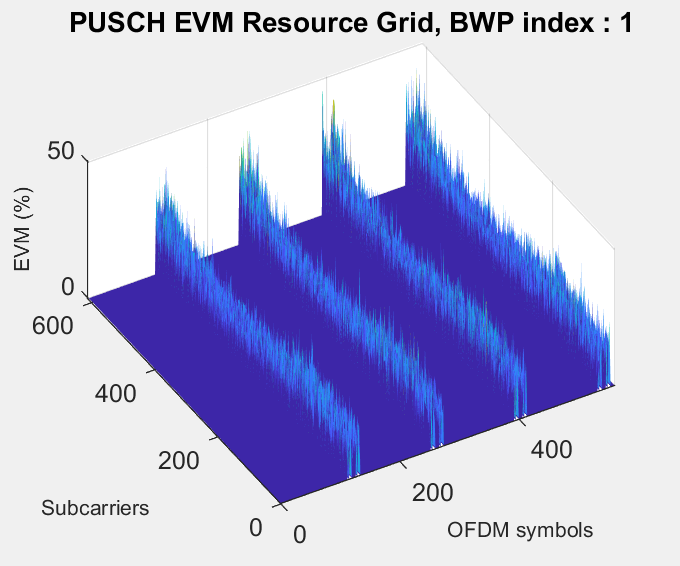

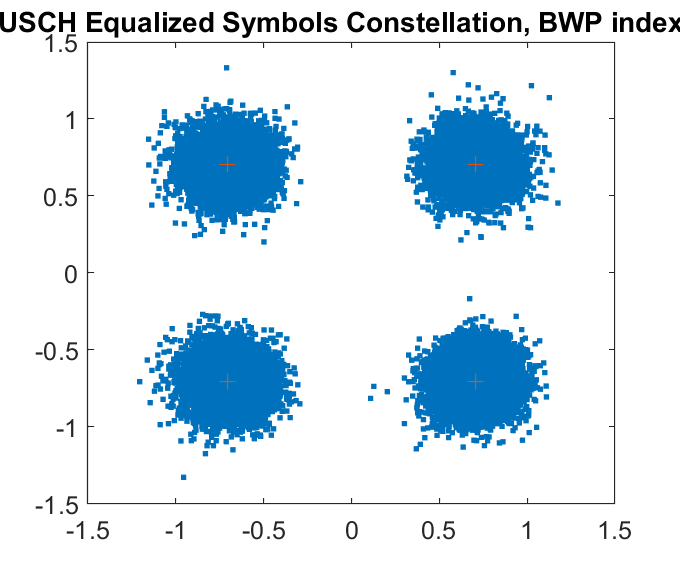

Peak EVM : 66.7914%


switch waveformFormat
    case {'TMs','FRCs','testModel','TestModel'}
        % import variable
        carrierCfg     = txWvCls.TM_config.class.Config;

        % Compute and display EVM measurements
        cfg = struct();
        cfg.Evm3Gpp = true;
        cfg.PlotEVM = true;
        cfg.DisplayEVM = true;

        [evmInfo,eqSym,refSym,throughputResults] = nrWaveformDemod_hNRPUSCHEVM(carrierCfg,rxWaveform,cfg);

    case {'pdsch'}
        txWvCls.pdschRx(rxWaveform,[],fnum+1017);
    case {'pusch'}
        txWvCls.puschRx(rxWaveform,[],fnum+1019);

end